# Pipline

Make Task File 

## Read file name subjects


clear all
Path_to_sess1_on = 'F:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\file_name_group\data_sess1_on.csv';
Path_to_sess1_off = 'F:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\file_name_group\data_sess2_on.csv';
Path_to_ctl = 'F:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\file_name_group\data_ctl.csv';
total_number_PD_On = 25;
total_number_PD_Off = 25;
total_number_CTL = 25;
fraction_of_PD_on_analysis = 0.08;
fraction_of_PD_off_analysis = 0.08;
fraction_of_PD_ctl_analysis = 0.08;

Range_on = sprintf('B2:B%d',1+fraction_of_PD_on_analysis*total_number_PD_On);
Range_off = sprintf('B2:B%d',1+fraction_of_PD_on_analysis*total_number_PD_Off);
Range_ctl = sprintf('B4:B%d',3+fraction_of_PD_on_analysis*total_number_CTL);

sess1_on = readtable(Path_to_sess1_on,'Range',Range_on)

Error using readtable (line 318)
Unable to find or open 'F:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\file_name_group\data_sess1_on.csv'. Check the path and filename or file permissions.

ctl = readtable(Path_to_ctl,'Range',Range_ctl)
sess1_off = readtable(Path_to_sess1_off,'Range',Range_off)

## Read Task File

clear all
eeglab
T = readtable('task_track_file.csv','Format','%d%s%s%s%d%s%d%s%d%s%d')

T = 75×11 table
    Var1        local_file_path                 raw_data_file_name                         preprocessed_one                flag1                  ERP_mat_file                  flag2                      PAC_dist                       flag3                PAC_dist_mean_channel                flag4
    ____    _______________________    ____________________________________    ________________________________________    _____    ________________________________________    _____    _____________________________________________    _____    _____________________________________________    _____

      0     {

## Preprocess

Highpass_low = 1; % in Hz
Highpass_High = 150; % in Hz
Notch_low = 59.9; % in Hz
Notch_High = 60.1;% in Hz
Notch_order = 16500;

% sub_num = [30,31,80];
% temp = size(sub_num);

% filepath = cell(temp(1),temp(2));
% channellocationfile = cell(temp(1),temp(2));
% temp = size(ctl);
% temp1 = size(sess1_on);
% temp2 = size(sess1_off);
% filename = cell(1,temp1(1)+temp(1)+temp2(1));
% filepath = cell(1,temp1(1)+temp(1)+temp2(1));
% channellocationfile = cell(1,temp1(1)+temp(1)+temp2(1));
Path = 'G:\\filmuniversity\\Master sharif\\MasterProject\\data\\parkinsons-oddball';
channellocationfile = sprintf('%s\\%s\\%s',Path,T{i,2}{1},'sub-001_ses-01_task-Rest_electrodes.tsv')

channellocationfile = 'G:\\filmuniversity\\Master sharif\\MasterProject\\data\\parkinsons-oddball\sub-001\ses-01\eeg\\sub-001_ses-01_task-Rest_electrodes.tsv'

% Saved_path = 'F:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\preprocess_check_data\RCSGS';
eeglab
for i=1:75
    load_path = sprintf('%s\\%s',Path,T{i,2}{1});
    EEG = pop_loadset(T{i,3}{1},load_path);
    EEG = pop_chanedit(EEG,'load',{channellocationfile ,'filetype','autodetect'});
    EEG = pop_select( EEG, 'nochannel',{'X','Y','Z','VEOG'});
    EEG = pop_eegfiltnew(EEG, 'locutoff',Highpass_low,'hicutoff',Highpass_High);
    EEG = pop_eegfiltnew(EEG, 'locutoff',Notch_low,'hicutoff',Notch_High,'filtorder',Notch_order,'revfilt',1);
%   figure; topoplot([],EEG.chanlocs, 'style', 'blank',  'electrodes', 'labelpoint', 'chaninfo', EEG.chaninfo);
    EEG1 = pop_clean_rawdata(EEG, 'FlatlineCriterion',5,'ChannelCriterion',0.8,'LineNoiseCriterion',12,'Highpass','off','BurstCriterion','off','WindowCriterion','off','BurstRejection','off','Distance','Euclidian');
    EEG = pop_interp(EEG1, EEG.chanlocs, 'spherical');
    EEG = pop_reref( EEG, []);
%     EEG.setname=[filename{i},'basr'];
%     pop_eegplot( EEG, 1, 1, 1);
    EEG = pop_clean_rawdata(EEG, 'FlatlineCriterion','off','ChannelCriterion','off','LineNoiseCriterion','off','Highpass','off','BurstCriterion',15,'WindowCriterion','off','BurstRejection','off','Distance','Euclidian');
%     EEG.setname=[filename{i},'afterasr'];
%     pop_eegplot( EEG, 1, 1, 1);
    EEG = pop_reref( EEG, []);
    EEG = pop_saveset( EEG, 'filename',T{i,4}{1},'filepath',load_path);
    T{i,5}(1) = 1;
    writetable(T,'task_track_file.csv')
end

pop_loadset(): loading file G:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\sub-001\ses-01\eeg\sub-001_ses-01_task-Rest_eeg.set ...
Reading float file 'G:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\sub-001\ses-01\eeg\sub-001_ses-01_task-Rest_eeg.fdt'...


readlocs(): 'tsv' format assumed from file extension


Removing 4 channel(s)...
Event resorted by increasing latencies.


pop_eegfiltnew() - performing 1651 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 150] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 150.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_eegfiltnew() - performing 16501 point bandstop (notch) filtering.
pop_eegfiltnew() - transition band width: 0.1 Hz
pop_eegfiltnew() - passband edge(s): [59.9 60.1] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [59.95 60.05] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Scanning for bad channels...
clean_channel:   1/117 blocks, 0.3 minutes remaining.
clean_channel:   2/117 blocks, 0.4 minutes remaining.
clean_channel:   3/117 blocks, 0.4 minutes remaining.
clean_channel:   4/117 blocks, 0.4 minutes remaining.
clean_channel:   5/117 blocks, 0.4 minutes remaining.
clean_channel:   6/117 blocks, 0.4 minutes remaining.
clean_channel:   7/117 blocks, 0.4 minutes remaining.
clean_channel:   8/117 blocks, 0.3 minutes remaining.
clean_channel:   9/117 blocks, 0.3 minutes remaining.
clean_channel:  10/117 blocks, 0.3 minutes remaining.
clean_channel:  11/117 blocks, 0.3 minutes remaining.
clean_channel:  12/117 blocks, 0.3 minutes remaining.
clean_channel:  13/117 blocks, 0.3 minutes remaining.
clean_channel:  14/117 blocks, 0.3 minutes remaining.
clean_channel:  15/117 blocks, 0.3 minutes remaining.
clean_channel:  16/117 blocks, 0.3 minutes remaining.
clean_channel:  17/117 blocks, 0.3 minutes remaining.
clean_channel:  18/117 blocks, 0.3 minutes remaining.

Interpolating 5 channels...


Re-referencing data


EEG.etc.clean_channel_mask present: Deleted.
Finding a clean section of the data...
Determining time window rejection thresholds...done.
Keeping 27.7% (163 seconds) of the data.


eeg_insertbound(): 55 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
eeg_checkset note: event field format 'visible' made uniform
eeg_checkset note: event field format 'code' made uniform
eeg_insertbound(): 55 boundary (break) events added.
Estimating calibration statistics; this may take a while...
Determining per-component thresholds...done.
Now cleaning data in 1361 blocks................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................

Re-referencing data


Saving dataset...


pop_loadset(): loading file G:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\sub-001\ses-02\eeg\sub-001_ses-02_task-Rest_eeg.set ...
Reading float file 'G:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\sub-001\ses-02\eeg\sub-001_ses-02_task-Rest_eeg.fdt'...


readlocs(): 'tsv' format assumed from file extension


Removing 4 channel(s)...
Event resorted by increasing latencies.


pop_eegfiltnew() - performing 1651 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 150] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 150.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_eegfiltnew() - performing 16501 point bandstop (notch) filtering.
pop_eegfiltnew() - transition band width: 0.1 Hz
pop_eegfiltnew() - passband edge(s): [59.9 60.1] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [59.95 60.05] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Scanning for bad channels...
clean_channel:   1/109 blocks, 0.3 minutes remaining.
clean_channel:   2/109 blocks, 0.3 minutes remaining.
clean_channel:   3/109 blocks, 0.3 minutes remaining.
clean_channel:   4/109 blocks, 0.3 minutes remaining.
clean_channel:   5/109 blocks, 0.3 minutes remaining.
clean_channel:   6/109 blocks, 0.3 minutes remaining.
clean_channel:   7/109 blocks, 0.3 minutes remaining.
clean_channel:   8/109 blocks, 0.3 minutes remaining.
clean_channel:   9/109 blocks, 0.3 minutes remaining.
clean_channel:  10/109 blocks, 0.3 minutes remaining.
clean_channel:  11/109 blocks, 0.3 minutes remaining.
clean_channel:  12/109 blocks, 0.3 minutes remaining.
clean_channel:  13/109 blocks, 0.3 minutes remaining.
clean_channel:  14/109 blocks, 0.3 minutes remaining.
clean_channel:  15/109 blocks, 0.3 minutes remaining.
clean_channel:  16/109 blocks, 0.3 minutes remaining.
clean_channel:  17/109 blocks, 0.3 minutes remaining.
clean_channel:  18/109 blocks, 0.3 minutes remaining.

Interpolating 4 channels...


Re-referencing data


EEG.etc.clean_channel_mask present: Deleted.
Finding a clean section of the data...
Determining time window rejection thresholds...done.
Keeping 27.5% (150 seconds) of the data.
eeg_insertbound(): 40 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
eeg_checkset note: event field format 'visible' made uniform
eeg_checkset note: event field format 'code' made uniform
eeg_insertbound(): 40 boundary (break) events added.
BUG 1971 WARNING: IF YOU ARE USING A SCRIPT WITTEN FOR A PREVIOUS VERSION OF EEGLAB (<2017)
TO CALL THIS FUNCTION, BECAUSE YOU ARE REJECTING THE ONSET OF THE DATA, EVENTS MIGHT HAVE
BEEN CORRUPTED. EVENT LATENCIES ARE NOW CORRECT (SEE https://sccn.ucsd.edu/wiki/EEGLAB_bug1971);
Estimating calibration statistics; this may take a while...
Determining per-component thresholds...done.
Now cleaning data in 1262 blocks.......................................................................................

Re-referencing data


Saving dataset...


## Preprocess

pop_loadset(): loading file F:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\sub-028\ses-01\eeg\sub-028_ses-01_task-Rest_eeg.set ...
Reading float file 'F:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\sub-028\ses-01\eeg\sub-028_ses-01_task-Rest_eeg.fdt'...


readlocs(): 'tsv' format assumed from file extension


Removing 4 channel(s)...
Event resorted by increasing latencies.


pop_eegfiltnew() - performing 1651 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 150] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 150.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_eegfiltnew() - performing 16501 point bandstop (notch) filtering.
pop_eegfiltnew() - transition band width: 0.1 Hz
pop_eegfiltnew() - passband edge(s): [59.9 60.1] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [59.95 60.05] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Scanning for bad channels...
clean_channel:   1/111 blocks, 0.3 minutes remaining.
clean_channel:   2/111 blocks, 0.3 minutes remaining.
clean_channel:   3/111 blocks, 0.3 minutes remaining.
clean_channel:   4/111 blocks, 0.3 minutes remaining.
clean_channel:   5/111 blocks, 0.3 minutes remaining.
clean_channel:   6/111 blocks, 0.3 minutes remaining.
clean_channel:   7/111 blocks, 0.3 minutes remaining.
clean_channel:   8/111 blocks, 0.3 minutes remaining.
clean_channel:   9/111 blocks, 0.3 minutes remaining.
clean_channel:  10/111 blocks, 0.3 minutes remaining.
clean_channel:  11/111 blocks, 0.3 minutes remaining.
clean_channel:  12/111 blocks, 0.3 minutes remaining.
clean_channel:  13/111 blocks, 0.3 minutes remaining.
clean_channel:  14/111 blocks, 0.3 minutes remaining.
clean_channel:  15/111 blocks, 0.2 minutes remaining.
clean_channel:  16/111 blocks, 0.2 minutes remaining.
clean_channel:  17/111 blocks, 0.2 minutes remaining.
clean_channel:  18/111 blocks, 0.2 minutes remaining.

Interpolating 3 channels...


Re-referencing data


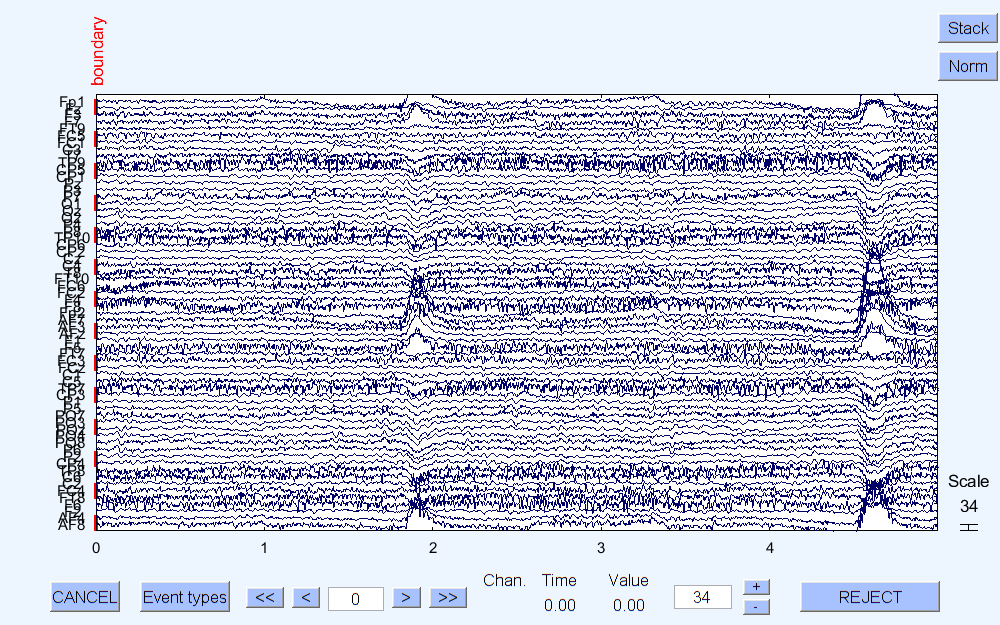

EEG.etc.clean_channel_mask present: Deleted.
Finding a clean section of the data...
Determining time window rejection thresholds...done.
Keeping 29.9% (166 seconds) of the data.
eeg_insertbound(): 128 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
eeg_checkset note: event field format 'visible' made uniform
eeg_checkset note: event field format 'code' made uniform
Event resorted by increasing latencies.
eeg_insertbound(): 128 boundary (break) events added.
BUG 1971 WARNING: IF YOU ARE USING A SCRIPT WITTEN FOR A PREVIOUS VERSION OF EEGLAB (<2017)
TO CALL THIS FUNCTION, BECAUSE YOU ARE REJECTING THE ONSET OF THE DATA, EVENTS MIGHT HAVE
BEEN CORRUPTED. EVENT LATENCIES ARE NOW CORRECT (SEE https://sccn.ucsd.edu/wiki/EEGLAB_bug1971);
Event resorted by increasing latencies.
Estimating calibration statistics; this may take a while...
Determining per-component thresholds...done.
Now cleaning data in 1287 blocks.....

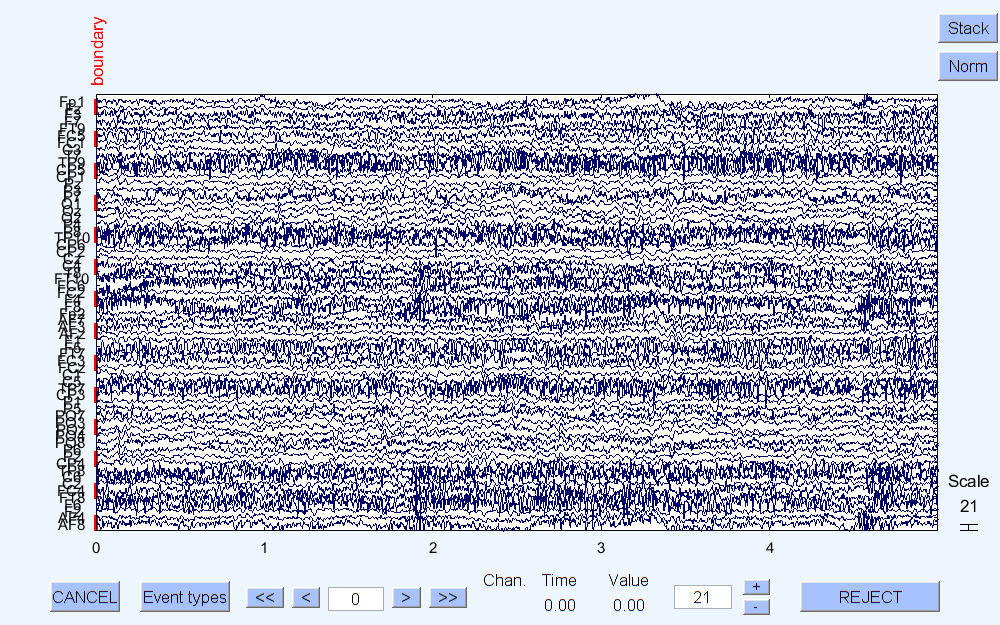

Re-referencing data


Saving dataset...


pop_loadset(): loading file F:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\sub-029\ses-01\eeg\sub-029_ses-01_task-Rest_eeg.set ...
Reading float file 'F:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\sub-029\ses-01\eeg\sub-029_ses-01_task-Rest_eeg.fdt'...


readlocs(): 'tsv' format assumed from file extension


Removing 4 channel(s)...
Event resorted by increasing latencies.


pop_eegfiltnew() - performing 1651 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 150] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 150.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_eegfiltnew() - performing 16501 point bandstop (notch) filtering.
pop_eegfiltnew() - transition band width: 0.1 Hz
pop_eegfiltnew() - passband edge(s): [59.9 60.1] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [59.95 60.05] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Scanning for bad channels...
clean_channel:   1/112 blocks, 0.3 minutes remaining.
clean_channel:   2/112 blocks, 0.3 minutes remaining.
clean_channel:   3/112 blocks, 0.3 minutes remaining.
clean_channel:   4/112 blocks, 0.3 minutes remaining.
clean_channel:   5/112 blocks, 0.3 minutes remaining.
clean_channel:   6/112 blocks, 0.3 minutes remaining.
clean_channel:   7/112 blocks, 0.3 minutes remaining.
clean_channel:   8/112 blocks, 0.3 minutes remaining.
clean_channel:   9/112 blocks, 0.3 minutes remaining.
clean_channel:  10/112 blocks, 0.3 minutes remaining.
clean_channel:  11/112 blocks, 0.3 minutes remaining.
clean_channel:  12/112 blocks, 0.3 minutes remaining.
clean_channel:  13/112 blocks, 0.3 minutes remaining.
clean_channel:  14/112 blocks, 0.3 minutes remaining.
clean_channel:  15/112 blocks, 0.3 minutes remaining.
clean_channel:  16/112 blocks, 0.3 minutes remaining.
clean_channel:  17/112 blocks, 0.3 minutes remaining.
clean_channel:  18/112 blocks, 0.3 minutes remaining.

Interpolating 4 channels...


Re-referencing data


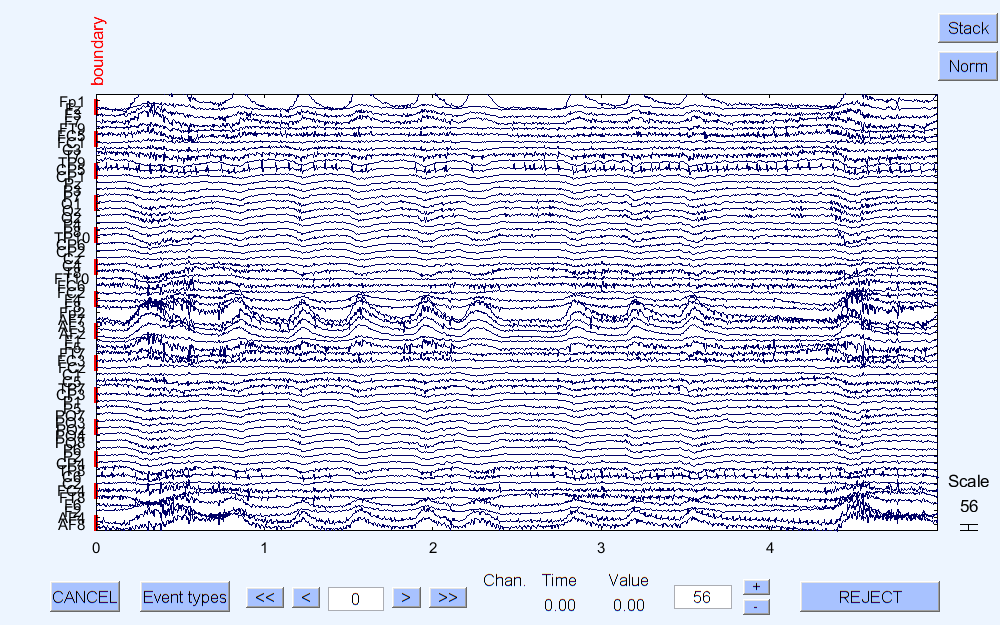

EEG.etc.clean_channel_mask present: Deleted.
Finding a clean section of the data...
Determining time window rejection thresholds...done.
Keeping 21.2% (119 seconds) of the data.
eeg_insertbound(): 72 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
eeg_checkset note: event field format 'visible' made uniform
eeg_checkset note: event field format 'code' made uniform
eeg_insertbound(): 72 boundary (break) events added.
Estimating calibration statistics; this may take a while...
Determining per-component thresholds...done.
Now cleaning data in 1297 blocks..............................................................................................................................................................................................................................................................................................................................................................................

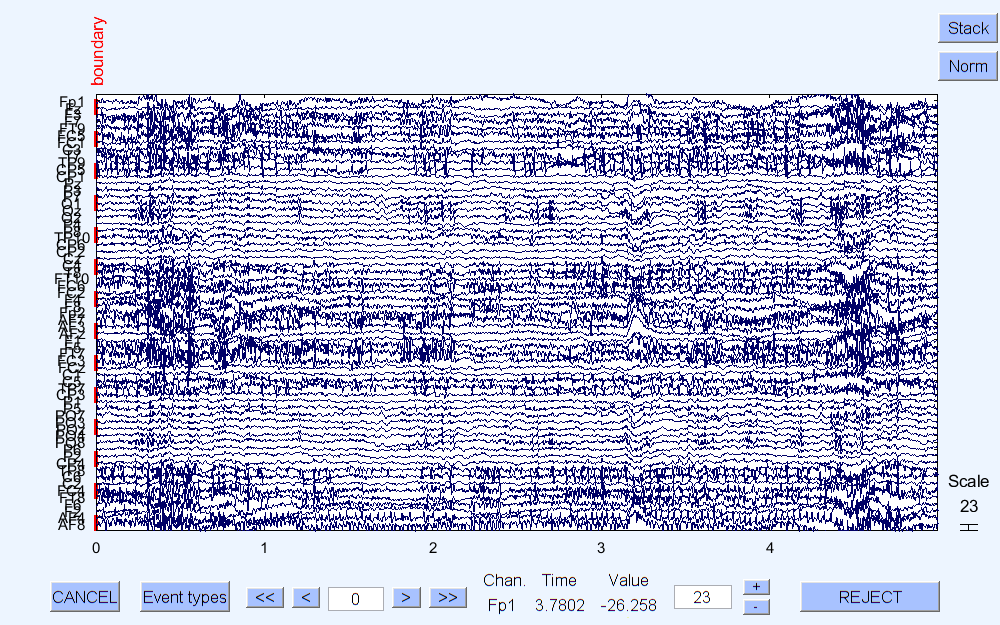

Re-referencing data


Saving dataset...


pop_loadset(): loading file F:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\sub-001\ses-01\eeg\sub-001_ses-01_task-Rest_eeg.set ...
Reading float file 'F:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\sub-001\ses-01\eeg\sub-001_ses-01_task-Rest_eeg.fdt'...


readlocs(): 'tsv' format assumed from file extension


Removing 4 channel(s)...
Event resorted by increasing latencies.


pop_eegfiltnew() - performing 1651 point bandpass filtering.
pop_eegfiltnew() - transition band width: 1 Hz
pop_eegfiltnew() - passband edge(s): [1 150] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.5 150.5] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


pop_eegfiltnew() - performing 16501 point bandstop (notch) filtering.
pop_eegfiltnew() - transition band width: 0.1 Hz
pop_eegfiltnew() - passband edge(s): [59.9 60.1] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [59.95 60.05] Hz
pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


Scanning for bad channels...
clean_channel:   1/117 blocks, 0.3 minutes remaining.
clean_channel:   2/117 blocks, 0.3 minutes remaining.
clean_channel:   3/117 blocks, 0.3 minutes remaining.
clean_channel:   4/117 blocks, 0.3 minutes remaining.
clean_channel:   5/117 blocks, 0.3 minutes remaining.
clean_channel:   6/117 blocks, 0.3 minutes remaining.
clean_channel:   7/117 blocks, 0.3 minutes remaining.
clean_channel:   8/117 blocks, 0.3 minutes remaining.
clean_channel:   9/117 blocks, 0.3 minutes remaining.
clean_channel:  10/117 blocks, 0.3 minutes remaining.
clean_channel:  11/117 blocks, 0.3 minutes remaining.
clean_channel:  12/117 blocks, 0.3 minutes remaining.
clean_channel:  13/117 blocks, 0.3 minutes remaining.
clean_channel:  14/117 blocks, 0.3 minutes remaining.
clean_channel:  15/117 blocks, 0.3 minutes remaining.
clean_channel:  16/117 blocks, 0.3 minutes remaining.
clean_channel:  17/117 blocks, 0.3 minutes remaining.
clean_channel:  18/117 blocks, 0.3 minutes remaining.

Interpolating 3 channels...


Re-referencing data


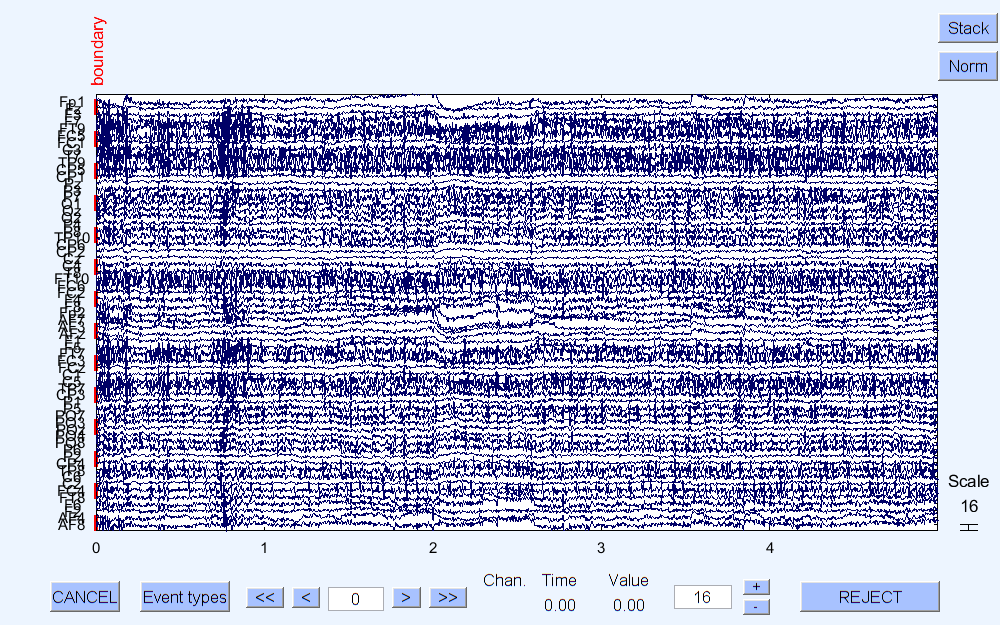

EEG.etc.clean_channel_mask present: Deleted.
Finding a clean section of the data...
Determining time window rejection thresholds...done.
Keeping 22.6% (133 seconds) of the data.


eeg_insertbound(): 41 boundary (break) events added.
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
eeg_checkset note: event field format 'visible' made uniform
eeg_checkset note: event field format 'code' made uniform
eeg_insertbound(): 41 boundary (break) events added.
Estimating calibration statistics; this may take a while...
Determining per-component thresholds...done.
Now cleaning data in 1361 blocks................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................................

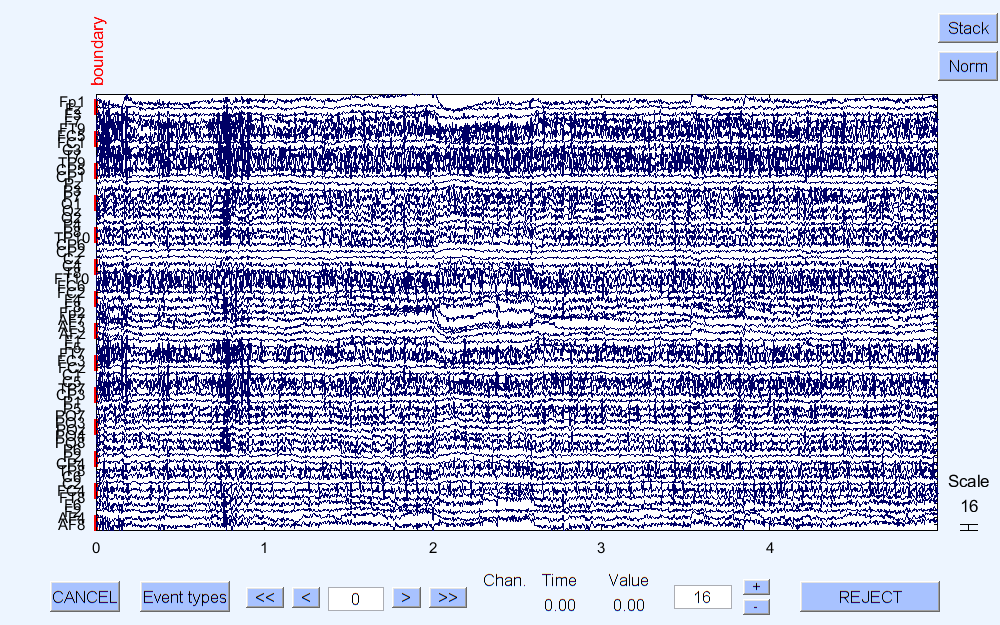

Re-referencing data


Saving dataset...


Highpass_low = 1; % in Hz
Highpass_High = 150; % in Hz
Notch_low = 59.9; % in Hz
Notch_High = 60.1;% in Hz
Notch_order = 16500;

sub_num = [30,31,80];
temp = size(sub_num);

% filepath = cell(temp(1),temp(2));
% channellocationfile = cell(temp(1),temp(2));
temp = size(ctl);
temp1 = size(sess1_on);
temp2 = size(sess1_off);
filename = cell(1,temp1(1)+temp(1)+temp2(1));
filepath = cell(1,temp1(1)+temp(1)+temp2(1));
channellocationfile = cell(1,temp1(1)+temp(1)+temp2(1));
Path = 'F:\\filmuniversity\\Master sharif\\MasterProject\\data\\parkinsons-oddball';
for i = 1:temp(1)
    filename{1,i} = sprintf('%s_ses-%02d_task-Rest_eeg.set',ctl{i,1}{1},1);
    filepath{1,i} = sprintf('%s\\%s\\ses-%02d\\eeg',Path,ctl{i,1}{1},1);
    channellocationfile{1,i} = sprintf('%s\\%s\\ses-%02d\\eeg\\%s_ses-%02d_task-Rest_electrodes.tsv',Path,ctl{i,1}{1},1,ctl{i,1}{1},1);
end
for j = 1:temp1(1)
    filename{1,i+j} = sprintf('%s_ses-%02d_task-Rest_eeg.set',sess1_on{j,1}{1},1);
    filepath{1,i+j} = sprintf('%s\\%s\\ses-%02d\\eeg',Path,sess1_on{j,1}{1},1);
    channellocationfile{1,i+j} = sprintf('%s\\%s\\ses-%02d\\eeg\\%s_ses-%02d_task-Rest_electrodes.tsv',Path,sess1_on{j,1}{1},1,sess1_on{j,1}{1},1);
end
t = i+j;
for a = 1:temp2(1)
    filename{1,t+a} = sprintf('%s_ses-%02d_task-Rest_eeg.set',sess1_off{a,1}{1},1);
    filepath{1,t+a} = sprintf('%s\\%s\\ses-%02d\\eeg',Path,sess1_off{a,1}{1},1);
    channellocationfile{1,t+a} = sprintf('%s\\%s\\ses-%02d\\eeg\\%s_ses-%02d_task-Rest_electrodes.tsv',Path,sess1_off{a,1}{1},1,sess1_off{a,1}{1},1);
end
Saved_path = 'F:\filmuniversity\Master sharif\MasterProject\data\parkinsons-oddball\preprocess_check_data\RCSGS';
% eeglab
for i=1:75
    EEG = pop_loadset(filename{i},filepath{i});
    EEG = pop_chanedit(EEG,'load',{channellocationfile{i} ,'filetype','autodetect'});
    EEG = pop_select( EEG, 'nochannel',{'X','Y','Z','VEOG'});
    EEG = pop_eegfiltnew(EEG, 'locutoff',Highpass_low,'hicutoff',Highpass_High);
    EEG = pop_eegfiltnew(EEG, 'locutoff',Notch_low,'hicutoff',Notch_High,'filtorder',Notch_order,'revfilt',1);
%   figure; topoplot([],EEG.chanlocs, 'style', 'blank',  'electrodes', 'labelpoint', 'chaninfo', EEG.chaninfo);
    EEG1 = pop_clean_rawdata(EEG, 'FlatlineCriterion',5,'ChannelCriterion',0.8,'LineNoiseCriterion',12,'Highpass','off','BurstCriterion','off','WindowCriterion','off','BurstRejection','off','Distance','Euclidian');
    EEG = pop_interp(EEG1, EEG.chanlocs, 'spherical');
    EEG = pop_reref( EEG, []);
    EEG.setname=[filename{i},'basr'];
    pop_eegplot( EEG, 1, 1, 1);
    EEG = pop_clean_rawdata(EEG, 'FlatlineCriterion','off','ChannelCriterion','off','LineNoiseCriterion','off','Highpass','off','BurstCriterion',15,'WindowCriterion','off','BurstRejection','off','Distance','Euclidian');
    EEG.setname=[filename{i},'afterasr'];
    pop_eegplot( EEG, 1, 1, 1);
    EEG = pop_reref( EEG, []);
    EEG = pop_saveset( EEG, 'filename',filename{i},'filepath',Saved_path);
end

## Make ERP

clear all

sub_num = [30,31,80];
temp = size(sub_num);
filename = cell(temp(1),temp(2));
filepath = cell(temp(1),temp(2));
channellocationfile = cell(temp(1),temp(2));

for i = 1:temp(2)
    filename{1,i} = sprintf('sub-%03d_ses-%02d_task-Rest_eeg.set',floor(sub_num(i)/2),mod(sub_num(i),2)+1);
%   filepath{1,i} = sprintf('G:\\filmuniversity\\Master sharif\\Master Project\\data\\parkinsons-oddball\\sub-%03d\\ses-%02d\\eeg',floor(sub_num(i)/2),mod(sub_num(i),2)+1);
%   channellocationfile{1,i} = sprintf('G:\\filmuniversity\\Master sharif\\Master Project\\data\\parkinsons-oddball\\sub-%03d\\ses-%02d\\eeg\\sub-%03d_ses-%02d_task-Rest_electrodes.tsv',floor(sub_num(i)/2),mod(sub_num(i),2)+1,floor(sub_num(i)/2),mod(sub_num(i),2)+1);
end

index_start = 122;

filepath1 = 'G:\filmuniversity\Master sharif\Master Project\data\parkinsons-oddball\preprocess_check_data';

number_samples = 1.2*500+1;
epochs = zeros(3,63,3,number_samples);

for i=1:3
    EEG = pop_loadset(filename{i},filepath1);
    temp1 = size(EEG.event);
    for j=1:63
        counter1 = 0; counter2= 0; counter3 = 0;
        for m=index_start:temp1(2)
            if strcmp(EEG.event(m).type,'S201')
                temp = zeros(1,number_samples);
                temp(:) = squeeze(epochs(i,j,1,:));
                epochs(i,j,1,:) = (temp*counter1 + EEG.data(j,EEG.event(m).latency-0.2*500:EEG.event(m).latency+500))/(counter1+1);
                counter1 = counter1 + 1;
            elseif strcmp(EEG.event(m).type,'S202') 
                temp = zeros(1,number_samples);
                temp(:) = squeeze(epochs(i,j,2,:));
                epochs(i,j,2,:) = (temp*counter2 + EEG.data(j,EEG.event(m).latency-0.2*500:EEG.event(m).latency+500))/(counter2+1);
                counter2 = counter2 + 1;
            elseif strcmp(EEG.event(m).type,'S200') 
                temp = zeros(1,number_samples);
                temp(:) = squeeze(epochs(i,j,3,:));
                epochs(i,j,3,:) = (temp*counter3 + EEG.data(j,EEG.event(m).latency-0.2*500:EEG.event(m).latency+500))/(counter3+1);
                counter3 = counter3 + 1;
            end    
        end   
    end    
end     

pop_loadset(): loading file G:\filmuniversity\Master sharif\Master Project\data\parkinsons-oddball\preprocess_check_data\sub-015_ses-01_task-Rest_eeg.set ...


Error using load
Unable to read file 'G:\filmuniversity\Master sharif\Master Project\data\parkinsons-oddball\preprocess_check_data\sub-015_ses-01_task-Rest_eeg.set'. No such file or directory.

Error in pop_loadset (line 134)
            TMPVAR = load('-mat', filename);

save('erp1.mat','epochs')

## PAC

clear all

Amplitude_Frequency_Range = 50:4:150;
Phase_Frequency = 4:1:13;
temp1 = size(Amplitude_Frequency_Range);
temp2 = size(Phase_Frequency);
load('erp1.mat')
temp = size(epochs);
pacs=zeros(3,63,3,temp1(2),temp2(2));
% counter=0;
for a=1:temp(1)
    for b=3:3:63
        for c=1:3
            for i=1:temp1(2)
                for j = 1:temp2(2)
                    pacs(a,b,c,i,j) = tfMVL(epochs(a,b,c,:),Amplitude_Frequency_Range(i),Phase_Frequency(j),500);
                end
            end
            fprintf('person %d channel %d stim %d  done\n',a,b,c)
%           counter=counter + 1;
        end    
    end
end 
frequency_details.high_start_fre = Amplitude_Frequency_Range(1);
frequency_details.high_end_fre = Amplitude_Frequency_Range(end);
frequency_details.step_high = 4;
frequency_details.low_start_fre = Phase_Frequency(1);
frequency_details.low_end_fre = Phase_Frequency(end);
frequency_details.step_low = 1;

save('pacs1.mat','pacs','frequency_details')

pacs = mean(pacs,2);

## Plot comodulogram

clear all
close all
load('pacs1.mat')
pacs = mean(pacs,2);
% pacs = mean(pacs,2);
high_range = [frequency_details.high_start_fre,frequency_details.high_end_fre];
low_range =  [frequency_details.low_start_fre,frequency_details.low_end_fre];
sub_num = [30,31,80];
subplot(3,3,1)
plot_comodulogram(squeeze(pacs(1,1,1,:,:)),high_range,low_range,sprintf('sub%d patient off medication S201 Standard Tone',floor(sub_num(1)/2)),frequency_details.step_high,frequency_details.step_low)
subplot(3,3,2)
plot_comodulogram(squeeze(pacs(2,1,1,:,:)),high_range,low_range,sprintf('sub%d patient on medication S201 Standard Tone ',floor(sub_num(2)/2)),frequency_details.step_high,frequency_details.step_low)
subplot(3,3,3)
plot_comodulogram(squeeze(pacs(3,1,1,:,:)),high_range,low_range,sprintf('sub%d healthy S201 Standard Tone ',floor(sub_num(3)/2)),frequency_details.step_high,frequency_details.step_low)
subplot(3,3,4)
plot_comodulogram(squeeze(pacs(1,1,2,:,:)),high_range,low_range,sprintf('sub%d patient off medication S202 Novel Tone ',floor(sub_num(1)/2)),frequency_details.step_high,frequency_details.step_low)
subplot(3,3,5)
plot_comodulogram(squeeze(pacs(2,1,2,:,:)),high_range,low_range,sprintf('sub%d patient on medication S202 Novel Tone ',floor(sub_num(2)/2)),frequency_details.step_high,frequency_details.step_low)
subplot(3,3,6)
plot_comodulogram(squeeze(pacs(3,1,2,:,:)),high_range,low_range,sprintf('sub%d healthy S202 Novel Tone ',floor(sub_num(3)/2)),frequency_details.step_high,frequency_details.step_low)
subplot(3,3,7)
plot_comodulogram(squeeze(pacs(1,1,3,:,:)),high_range,low_range,sprintf('sub%d patient off medication S200 Target Tone ',floor(sub_num(1)/2)),frequency_details.step_high,frequency_details.step_low)
subplot(3,3,8)
plot_comodulogram(squeeze(pacs(2,1,3,:,:)),high_range,low_range,sprintf('sub%d patient on medication S200 Target Tone ',floor(sub_num(2)/2)),frequency_details.step_high,frequency_details.step_low)
subplot(3,3,9)
plot_comodulogram(squeeze(pacs(3,1,3,:,:)),high_range,low_range,sprintf('sub%d healthy S200 Target Tone ',floor(sub_num(3)/2)),frequency_details.step_high,frequency_details.step_low)

clear all
close all
load('channel.mat')
load('pacs1.mat')
for i=3:3:63
    % pacs = mean(pacs,2);
    figure;
    high_range = [frequency_details.high_start_fre,frequency_details.high_end_fre];
    low_range =  [frequency_details.low_start_fre,frequency_details.low_end_fre];
    sub_num = [30,31,80];
    subplot(3,3,1)
    plot_comodulogram(squeeze(pacs(1,i,1,:,:)),high_range,low_range,sprintf('sub%d patient off medication S201 Standard Tone channel %s',floor(sub_num(1)/2),a(1,i).labels),frequency_details.step_high,frequency_details.step_low)
    subplot(3,3,2)
    plot_comodulogram(squeeze(pacs(2,i,1,:,:)),high_range,low_range,sprintf('sub%d patient on medication S201 Standard Tone channel %s',floor(sub_num(2)/2),a(1,i).labels),frequency_details.step_high,frequency_details.step_low)
    subplot(3,3,3)
    plot_comodulogram(squeeze(pacs(3,i,1,:,:)),high_range,low_range,sprintf('sub%d healthy S201 Standard Tone channel %s',floor(sub_num(3)/2),a(1,i).labels),frequency_details.step_high,frequency_details.step_low)
    subplot(3,3,4)
    plot_comodulogram(squeeze(pacs(1,i,2,:,:)),high_range,low_range,sprintf('sub%d patient off medication S202 Novel Tone channel %s',floor(sub_num(1)/2),a(1,i).labels),frequency_details.step_high,frequency_details.step_low)
    subplot(3,3,5)
    plot_comodulogram(squeeze(pacs(2,i,2,:,:)),high_range,low_range,sprintf('sub%d patient on medication S202 Novel Tone channel %s',floor(sub_num(2)/2),a(1,i).labels),frequency_details.step_high,frequency_details.step_low)
    subplot(3,3,6)
    plot_comodulogram(squeeze(pacs(3,i,2,:,:)),high_range,low_range,sprintf('sub%d healthy S202 Novel Tone channel %s',floor(sub_num(3)/2),a(1,i).labels),frequency_details.step_high,frequency_details.step_low)
    subplot(3,3,7)
    plot_comodulogram(squeeze(pacs(1,i,3,:,:)),high_range,low_range,sprintf('sub%d patient off medication S200 Target Tone channel %s',floor(sub_num(1)/2),a(1,i).labels),frequency_details.step_high,frequency_details.step_low)
    subplot(3,3,8)
    plot_comodulogram(squeeze(pacs(2,i,3,:,:)),high_range,low_range,sprintf('sub%d patient on medication S200 Target Tone channel %s',floor(sub_num(2)/2),a(1,i).labels),frequency_details.step_high,frequency_details.step_low)
    subplot(3,3,9)
    plot_comodulogram(squeeze(pacs(3,i,3,:,:)),high_range,low_range,sprintf('sub%d healthy S200 Target Tone channel %s',floor(sub_num(3)/2),a(1,i).labels),frequency_details.step_high,frequency_details.step_low)
end